## Initialisation du simulink : Methode Pur Pursuit

### On defini les variables

#### Constantes

v = 5 % vitesse constante (m/s)

v = 5

L = 2 % distance entre les roues avant et arrieres (m)

L = 2


T = 3*60 % Temps de simulation (s)

T = 180

Te = 0.01 % Temps d'echantillonage (s)

Te = 0.0100

#### Variables

Initialisation à 0 pour toutes les variables

psi = pi/2 %Yaw

psi = 1.5708

x = 0 % coordonnées du centre de gravité de la voiture

x = 0

y = 0

y = 0

Pour l'instant le chemin a suivre est un sin

Xg = 0:Te:T

Xg =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


Yg = sin(Xg*0.008)

Yg =          0    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0022    0.0022    0.0023    0.0024    0.0025    0.0026    0.0026    0.0027    0.0028    0.0029    0.0030    0.0030    0.0031    0.0032    0.0033    0.0034    0.0034    0.0035    0.0036    0.0037    0.0038    0.0038    0.0039



Xg_sim.time = Xg';
Xg_sim.signals.values = Xg';

Yg_sim.time = Xg';
Yg_sim.signals.values = Yg';

xg = Xg(1)

xg = 0

yg = Yg(1)

yg = 0

#### Pur Pursuit

d=2 %Lookahead distance

d = 2

test

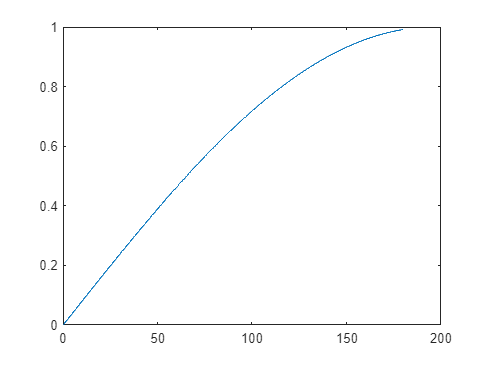

plot(Xg,Yg)

## Run Simulink

open_system('C:\Users\leonj\OneDrive\Documents\ETS\Cours\SYS802\Projet\Pur_Pursuit\V1\Pur_Pursuit.slx')